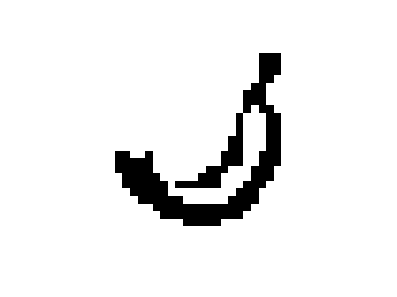

clear all;
% Image Size
N = 16;
M = 32*N;

% Reading the audio signal
[signal, Fs] = audioread('pop.wav');
x1 = signal(1:M^2);
x1 = reshape(x1,1,M^2);
x = reshape(x1, M, M);

% Key for random sequence
key = 7;

% Reading the image to be embedded
img = imread('test.jpg');
% Binarize the image
gray_img = rgb2gray(img);
binary_img = imbinarize(gray_img);
w1 = imbinarize(gray_img);
imshow(binary_img)

% 3 Level 2-D Wavelet transform
[L,H,V,D] = dwt2(x,'haar','sym');
[H1,H2,H3,H4] = dwt2(H,'haar','sym');
[V1,V2,V3,V4] = dwt2(V,'haar','sym');
[A1,A2,A3,A4] = dwt2(H2,'haar','sym');
[B1,B2,B3,B4] = dwt2(H3,'haar','sym');
[C1,C2,C3,C4] = dwt2(V2,'haar','sym');
[D1,D2,D3,D4] = dwt2(V3,'haar','sym');

a = 4 + zeros(1,16);
b = 4 + zeros(1,16);
[L1, L2] = size(A2);
d=zeros(L1,L2);

% Finding DCT of sub-band H2-A2
n_A2=mat2cell(A2,a,b);
nA2=mat2cell(d,a,b);
for i=1:16
    for j=1:16
        nA2{i,j}=dct2(n_A2{i,j});
    end
end

% Finding DCT of H3-B2
n_B2=mat2cell(B2,a,b);
nB2=mat2cell(d,a,b);
for i=1:16
    for j=1:16
        nB2{i,j}=dct2(n_B2{i,j});
    end
end

% Finding DCT of sub-band V2-C2
n_C2=mat2cell(C2,a,b);
nC2=mat2cell(d,a,b);
for i=1:16
    for j=1:16
        nC2{i,j}=dct2(n_C2{i,j});
    end
end

% Finding DCT of sub-band V3-D2
n_D2=mat2cell(D2,a,b);
nD2=mat2cell(d,a,b);
for i=1:16
    for j=1:16
        nD2{i,j}=dct2(n_D2{i,j});
    end
end

%% UNCORRELATED PSEUDO RANDOM SEQUENCE GENERATOR

G=key;
%Generation of first m-sequence using generator polynomial [45]
sd1 =[0 0 0 0 1];             % Initial state of Shift register
PN1=[];                       % First m-sequence
for j=1:G
    PN1=[PN1 sd1(5)];
    if sd1(1)==sd1(4)
        temp1=0;
    else temp1=1;
    end
    sd1(1)=sd1(2);
    sd1(2)=sd1(3);
    sd1(3)=sd1(4);
    sd1(4)=sd1(5);
    sd1(5)=temp1;
end
sd2 =[0 0 0 0 1];             % Initial state of Shift register
PN2=[];                       % Second m-sequence
for j=1:G
    PN2=[PN2 sd2(5)];
    if sd2(1)==sd2(2)
        temp1=0;
    else temp1=1;
    end
    if sd2(4)==temp1
        temp2=0;
    else temp2=1;
    end
    if sd2(5)==temp2
        temp3=0;
    else temp3=1;
    end
    sd2(1)=sd2(2);
    sd2(2)=sd2(3);
    sd2(3)=sd2(4);
    sd2(4)=sd2(5);
    sd2(5)=temp3;
end

% Coefficient of watermarking
alpha = 0.1;

% Watermarking of A2 coefficients
for p=1:16
    for q=1:16
        if w1(p,q)==0
            nA2{p,q}(1,3)=nA2{p,q}(1,3)+alpha*PN1(1);
            nA2{p,q}(1,4)=nA2{p,q}(1,4)+alpha*PN1(2);
            nA2{p,q}(2,2)=nA2{p,q}(2,2)+alpha*PN1(3);
            nA2{p,q}(2,3)=nA2{p,q}(2,3)+alpha*PN1(4);
            nA2{p,q}(3,1)=nA2{p,q}(3,1)+alpha*PN1(5);
            nA2{p,q}(3,2)=nA2{p,q}(3,2)+alpha*PN1(6);
            nA2{p,q}(4,1)=nA2{p,q}(4,1)+alpha*PN1(7);
        else
            nA2{p,q}(1,3)=nA2{p,q}(1,3)+alpha*PN2(1);
            nA2{p,q}(1,4)=nA2{p,q}(1,4)+alpha*PN2(2);
            nA2{p,q}(2,2)=nA2{p,q}(2,2)+alpha*PN2(3);
            nA2{p,q}(2,3)=nA2{p,q}(2,3)+alpha*PN2(4);
            nA2{p,q}(3,1)=nA2{p,q}(3,1)+alpha*PN2(5);
            nA2{p,q}(3,2)=nA2{p,q}(3,2)+alpha*PN2(6);
            nA2{p,q}(4,1)=nA2{p,q}(4,1)+alpha*PN2(7);
        end
    end
end

for i=1:16
    for j=1:16
        n_A2{i,j}=idct2(nA2{i,j});
    end
end
A2=cell2mat(n_A2);

% Watermarking of B2
for p=1:16
    for q=1:16
        if w1(p,16+q)==0
            nB2{p,q}(1,3)=nB2{p,q}(1,3)+alpha*PN1(1);
            nB2{p,q}(1,4)=nB2{p,q}(1,4)+alpha*PN1(2);
            nB2{p,q}(2,2)=nB2{p,q}(2,2)+alpha*PN1(3);
            nB2{p,q}(2,3)=nB2{p,q}(2,3)+alpha*PN1(4);
            nB2{p,q}(3,1)=nB2{p,q}(3,1)+alpha*PN1(5);
            nB2{p,q}(3,2)=nB2{p,q}(3,2)+alpha*PN1(6);
            nB2{p,q}(4,1)=nB2{p,q}(4,1)+alpha*PN1(7);
        else
            nB2{p,q}(1,3)=nB2{p,q}(1,3)+alpha*PN2(1);
            nB2{p,q}(1,4)=nB2{p,q}(1,4)+alpha*PN2(2);
            nB2{p,q}(2,2)=nB2{p,q}(2,2)+alpha*PN2(3);
            nB2{p,q}(2,3)=nB2{p,q}(2,3)+alpha*PN2(4);
            nB2{p,q}(3,1)=nB2{p,q}(3,1)+alpha*PN2(5);
            nB2{p,q}(3,2)=nB2{p,q}(3,2)+alpha*PN2(6);
            nB2{p,q}(4,1)=nB2{p,q}(4,1)+alpha*PN2(7);
        end
    end
end

for i=1:16
    for j=1:16
        n_B2{i,j}=idct2(nB2{i,j});
    end
end
B2=cell2mat(n_B2);

% Watermarking of C2
for p=1:16
    for q=1:16
        if w1(p+16,q)==0
            nC2{p,q}(1,3)=nC2{p,q}(1,3)+alpha*PN1(1);
            nC2{p,q}(1,4)=nC2{p,q}(1,4)+alpha*PN1(2);
            nC2{p,q}(2,2)=nC2{p,q}(2,2)+alpha*PN1(3);
            nC2{p,q}(2,3)=nC2{p,q}(2,3)+alpha*PN1(4);
            nC2{p,q}(3,1)=nC2{p,q}(3,1)+alpha*PN1(5);
            nC2{p,q}(3,2)=nC2{p,q}(3,2)+alpha*PN1(6);
            nC2{p,q}(4,1)=nC2{p,q}(4,1)+alpha*PN1(7);
        else
            nC2{p,q}(1,3)=nC2{p,q}(1,3)+alpha*PN2(1);
            nC2{p,q}(1,4)=nC2{p,q}(1,4)+alpha*PN2(2);
            nC2{p,q}(2,2)=nC2{p,q}(2,2)+alpha*PN2(3);
            nC2{p,q}(2,3)=nC2{p,q}(2,3)+alpha*PN2(4);
            nC2{p,q}(3,1)=nC2{p,q}(3,1)+alpha*PN2(5);
            nC2{p,q}(3,2)=nC2{p,q}(3,2)+alpha*PN2(6);
            nC2{p,q}(4,1)=nC2{p,q}(4,1)+alpha*PN2(7);
        end
    end
end

for i=1:16
    for j=1:16
        n_C2{i,j}=idct2(nC2{i,j});
    end
end
C2=cell2mat(n_C2);

% Watermarking of D2
for p=1:16
    for q=1:16
        if w1(p+16,q+16)==0
            nD2{p,q}(1,3)=nD2{p,q}(1,3)+alpha*PN1(1);
            nD2{p,q}(1,4)=nD2{p,q}(1,4)+alpha*PN1(2);
            nD2{p,q}(2,2)=nD2{p,q}(2,2)+alpha*PN1(3);
            nD2{p,q}(2,3)=nD2{p,q}(2,3)+alpha*PN1(4);
            nD2{p,q}(3,1)=nD2{p,q}(3,1)+alpha*PN1(5);
            nD2{p,q}(3,2)=nD2{p,q}(3,2)+alpha*PN1(6);
            nD2{p,q}(4,1)=nD2{p,q}(4,1)+alpha*PN1(7);
        else
            nD2{p,q}(1,3)=nD2{p,q}(1,3)+alpha*PN2(1);
            nD2{p,q}(1,4)=nD2{p,q}(1,4)+alpha*PN2(2);
            nD2{p,q}(2,2)=nD2{p,q}(2,2)+alpha*PN2(3);
            nD2{p,q}(2,3)=nD2{p,q}(2,3)+alpha*PN2(4);
            nD2{p,q}(3,1)=nD2{p,q}(3,1)+alpha*PN2(5);
            nD2{p,q}(3,2)=nD2{p,q}(3,2)+alpha*PN2(6);
            nD2{p,q}(4,1)=nD2{p,q}(4,1)+alpha*PN2(7);
        end
    end
end

for i=1:16
    for j=1:16
        n_D2{i,j}=idct2(nD2{i,j});
    end
end
D2=cell2mat(n_D2);

% Taking IDWT and IDCT
H2 = idwt2(A1,A2,A3,A4,'haar','sym');
H3 = idwt2(B1,B2,B3,B4,'haar','sym');
H = idwt2(H1,H2,H3,H4,'haar','sym');
V2 = idwt2(C1,C2,C3,C4,'haar','sym');
V3 = idwt2(D1,D2,D3,D4,'haar','sym');
V = idwt2(V1,V2,V3,V4,'haar','sym');

x_new = idwt2(L,H,V,D,'haar','sym');
y1 = reshape(x_new,1,M^2);
SNR = snr(y1,x1);


ok_noise =0;        % select 1 for adding the particular disturbance to host audio
ok_filtering=0;
ok_cropping=0;
ok_resampling=0;

if ok_noise
    % Additional noise
    y1 = awgn(y1,10,'measured');
end

if ok_filtering
    % Filtering
    myfilter = ones(512,1);
    myfilter = myfilter/sum(myfilter);
    y1   = filter(myfilter,1,y1);
end

if ok_cropping
    % Cropping
    Lmin = round(L/11);
    Lmax = round(5*L/11);
    y1(1:1,1:Lmin)   = 0;
    y1(1:1,Lmax:end) = 0;
end
if ok_resampling
    % Resampling
    Fs_0 = Fs;
    Fs_1 = round(Fs/9);
    y1 = resample(y1,Fs_1,Fs_0);
    y1 = resample(y1,Fs_0,Fs_1);
    if length(y1)<L
        y1(end+L) = 0;
    end
    if length(y1)>L
        y1 = y1(1:L);
    end
end

signal(1:M^2) = y1;
audiowrite('Watermarked_out.wav',signal, Fs);